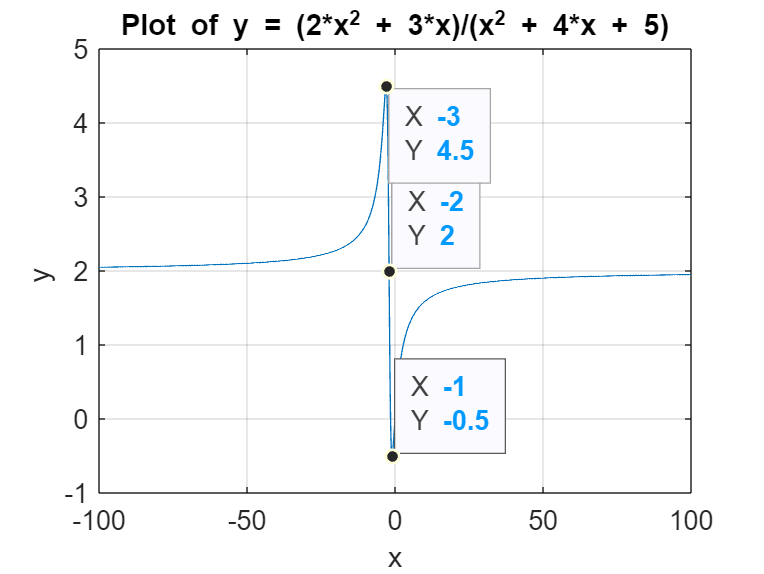

%%värden för samma graf med större definitionsmängd
x_values = -100:0.1:100;
y_values = quad(x_values);

plot(x_values,y_values)
grid on;
xlabel('x');
ylabel('y ');
title('Plot of y = (2*x^2 + 3*x)/(x^2 + 4*x + 5)');

%%för att rita punkten grafen är symmetriskt runt 
ax2 = gca;
chart2 = ax2.Children(1);

%%punkten (-2,2) vilket är punkten grafen är symmetrisk runt
% ficks ut genom att lägga ihop max värdemängd vid punkt (-3,4.5)
%% och den minimala värdemängden vid punkt (-1,0.5)
% och dela på två, max/min punkter visas tydligt på graf
datatip(chart2,-2,2);
%%punkter nedan för min/max punkter
ax5 = gca;
chart5 = ax5.Children(1);
datatip(chart5,-3,4.5);
datatip(chart5,-1,-0.5);


%%värden för samma graf fast mindre definitionsmängd
x_values_2 = -15:0.1:15

x_values_2 =   -15.0000  -14.9000  -14.8000  -14.7000  -14.6000  -14.5000  -14.4000  -14.3000  -14.2000  -14.1000  -14.0000  -13.9000  -13.8000  -13.7000  -13.6000  -13.5000  -13.4000  -13.3000  -13.2000  -13.1000  -13.0000  -12.9000  -12.8000  -12.7000  -12.6000  -12.5000  -12.4000  -12.3000  -12.2000  -12.1000  -12.0000  -11.9000  -11.8000  -11.7000  -11.6000  -11.5000  -11.4000  -11.3000  -11.2000  -11.1000  -11.0000  -10.9000  -10.8000  -10.7000  -10.6000  -10.5000  -10.4000  -10.3000  -10.2000  -10.1000


y_values_2 = quad(x_values_2)

y_values_2 =     2.3824    2.3853    2.3883    2.3913    2.3943    2.3975    2.4006    2.4038    2.4071    2.4104    2.4138    2.4172    2.4207    2.4243    2.4279    2.4315    2.4352    2.4390    2.4429    2.4468    2.4508    2.4549    2.4590    2.4632    2.4675    2.4719    2.4764    2.4809    2.4855    2.4902    2.4950    2.4999    2.5049    2.5100    2.5152    2.5205    2.5260    2.5315    2.5371    2.5429    2.5488    2.5548    2.5609    2.5672    2.5736    2.5802    2.5869    2.5938    2.6008    2.6080



plot(x_values_2,y_values_2)
grid on;
xlabel('x');
ylabel('y ');
title('Plot of y = (2*x^2 + 3*x)/(x^2 + 4*x + 5)');

%%alla punkter som visas i graf med mindre definitionsmängd
ax = gca;
chart = ax.Children(1);
datatip(chart,-2,2)

ans =   DataTip (X -2, Y 2) with properties:

    DataIndex: 131
     Location: 'northeast'
       Parent: [1×1 Line]

  Show all properties


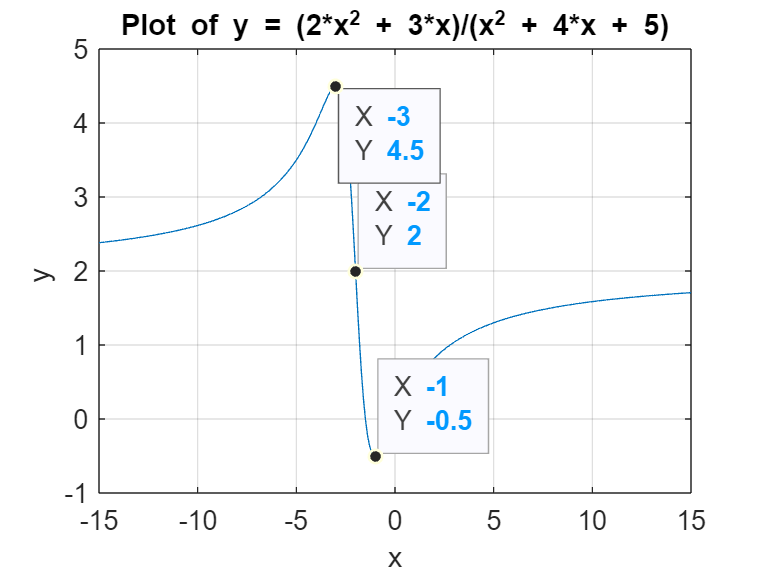

ax3 = gca;
chart3 = ax3.Children(1);
datatip(chart3,-1,-0.5);
ax4 = gca;
chart4 = ax4.Children(1);
datatip(chart4,-3,4.5);

function y = quad(x)%% funktionen som bildar grafen
a = (2*x.^2 + 3*x);
b = (x.^2 + 4*x+5);
y= a ./ b;
end